# Limited Slip Differential (LSD) - Study based on iRacing © Simulation

## Preamble

Within

## Plot Description:

The plot below shows the performance of open and a limited slip differential on a split surface (ice and tarmac). The limited slip differential locks instantly when the left wheel encounters the icy patch. As a result, the wheels turn at the same speed and more torque is applied to the wheel on the high friction surface. The open differential does not lock. The same torque is applied to both wheels, resulting in the right wheel slipping extensively on the icy patch.

% Generate simulation results if they don't exist
Sim_Time = 5;
FrictionFaces = 4 ; Friction_Faces_Min = FrictionFaces;
Friction_Faces_Max = 6;
Friction_Faces_Step =2;
%Road_Surface_Left_Wheel;


if ~exist('simlog_LimitedSlipDifferentialWithClutches', 'var')
    sim('LimitedSlipDifferentialWithClutches')
end

% Reuse figure if it exists, else create new figure
if ~exist('h2_LimitedSlipDifferentialWithClutches', 'var') || ...
        ~isgraphics(h2_LimitedSlipDifferentialWithClutches, 'figure')
    h2_LimitedSlipDifferentialWithClutches = figure('Name', 'LimitedSlipDifferentialWithClutches');
end
figure(h2_LimitedSlipDifferentialWithClutches)
clf(h2_LimitedSlipDifferentialWithClutches)
set(gcf,'Units','normalized','Position',[0 0 1 1]); 

%Prepare figures
temp_colororder = get(gca,'defaultAxesColorOrder');
simlog_handles(1) = subplot(2, 1, 2);

nFrictionFaceSettings = fix((Friction_Faces_Max-Friction_Faces_Min)/Friction_Faces_Step)+1;

% Simulate Shaft-Torques for different number of friction surfaces
for n =1:1:nFrictionFaceSettings
    FrictionFaces = Friction_Faces_Min + (n-1)*Friction_Faces_Step
    %execute simulation
    sim('LimitedSlipDifferentialWithClutches')
    %get simulation results
    simlog_t = simlog_LimitedSlipDifferentialWithClutches.Limited_Slip_Torque_Source.t.series.time;
    simlog_limitslipLwhlTrq = simlog_LimitedSlipDifferentialWithClutches.Tires_Limited_Slip_Differential.Sensor_Left.Torque_Sensor.t.series.values('N*m');
    %simlog_limitslipRwhlTrq = simlog_LimitedSlipDifferentialWithClutches.Tires_Limited_Slip_Differential.Sensor_Right.Torque_Sensor.t.series.values('N*m');
    %simlog_openLwhlTrq = simlog_LimitedSlipDifferentialWithClutches.Open_Differential.sun_planet_left.t_S.series.values('N*m');
    %simlog_openRwhlTrq = simlog_LimitedSlipDifferentialWithClutches.Open_Differential.sun_planet_left.t_S.series.values('N*m');
    simlog_torque = simlog_LimitedSlipDifferentialWithClutches.Limited_Slip_Torque_Source.t.series.values('N*m');

    %Plot Shaft Torques

    plot(simlog_t, simlog_limitslipLwhlTrq, 'LineWidth', 1,'Color',temp_colororder(n,:), 'DisplayName', compose("%d-left",FrictionFaces));
    hold on
    %plot(simlog_t, simlog_limitslipRwhlTrq, '--','LineWidth', 2,'Color',temp_colororder(n,:), 'DisplayName', compose("%d-right",FrictionFaces));
    
    %plot(simlog_t, -simlog_openLwhlTrq, 'LineWidth', 1,'Color',temp_colororder(2,:))
    %plot(simlog_t, -simlog_openRwhlTrq, 'LineStyle','--', 'LineWidth', 2,'Color',temp_colororder(2,:))


end

FrictionFaces = 4

FrictionFaces = 6


%complete figure shaft-torques
ylabel('Shaft-Torque (N*m)')
hold off
grid on
title('Shaft Torques on Split Surface Test with different number of friction plates')
ylabel('Torque (N*m)')
legend_shaft_torque = legend;
legend_shaft_torque.Title.String = "Number of surfaces";
legend_shaft_torque.Location = 'northeast';
%txt = ['Limited Slip Left with ', num2str(NumberOfFrictionSurfaces)," friction surfaces"];
%legend({compose("LSD %d plates (left)",NumberOfFrictionSurfaces),compose("LSD %d plates (right)",NumberOfFrictionSurfaces)},'Location','northwest');
%legend({'Limited Slip Left','Limited Slip Right','Open Left','Open Right'},'Location','NorthWest');





%-------------
% Plot results
%-------------




%Calculate and Plot Surface and Engine Torque
temp_surface = logsout_LimitedSlipDifferentialWithClutches.get('Wheel_Surface');

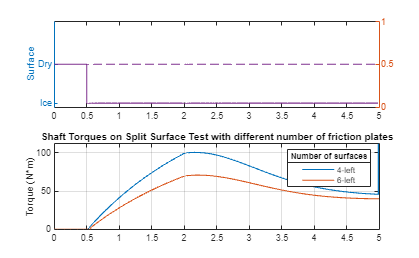

simlog_handles(2) = subplot(2, 1, 1);
yyaxis left
plot(temp_surface.Values.Time, temp_surface.Values.Data, 'LineWidth', 1,'Color',temp_colororder(4,:))
ylabel('Surface')
set(gca,'YLim',[0.9 3.1],'YTick',1:3)
set(gca,'YTickLabel',{'Ice' 'Dry' 'Wet'})

set(gca,'YColor',temp_colororder(4,:))
yyaxis right
plot(simlog_t, simlog_torque, 'LineWidth', 1,'Color',temp_colororder(5,:))
set(gca,'YColor',temp_colororder(5,:))
grid on
title('Surface and Engine Torque')
ylabel('Engine Torque (N*m)')
xlabel('Time (s)')
legend({'Left Surface','Right Surface','Engine Torque'},'Location','West');

linkaxes(simlog_handles, 'x')

% Remove temporary variables
clear simlog_t simlog_handles
clear simlog_torque
clear simlog_openLwhlTrq simlog_openRwhlTrq
clear simlog_limitslipLwhlTrq simlog_limitslipRwhlTrq
clear temp_colororder temp_surface

*Copyright 2016 The MathWorks, Inc.*